clear all
close all
clc

% Select file to read data from
str_mainpath = "D:\jnofech_Maglev_Project\00_WORKSTATION\MATLAB Training\Measurement Data\";
str_date = "2024-05-07";
% str_fname = "rec1_0017.mf4";
% str_fname = "rec1_0200.mf4";
% str_fname = "rec1_0003.mf4";
% str_fname = "rec1_0002.mf4";    % Figure used in thesis (ccr_idx = 31)

% % IMPORTANT RECORDINGS (2024-05-07+; uses raw z for "PI"+"feedforward" control and butter(6,0.6) xyz for everything else):
% % ^ Either use ALL RAW or ALL BUTTERED xyz data; do not mix and match since they are slightly desynced!

% Measurement, during which magnet partially leaves XY detection range
% str_fname = "rec1_0011.mf4";        % Relevant indices: <array>(2660:end)

% Stationary levitation at z=0.002 with z-jitter:
% std(x,y,z)=(2.10,1.83,2.22) micron in non-jittery areas (using "buttered" signal)
% str_date = "2024-05-07";
% str_fname = "rec1_00000.mf4";

% % Resting on platform with amplifiers off:
% str_date = "2024-05-07";
str_fname = "rec1_000.mf4";


fullpath = str_mainpath+str_date+"\"+str_fname;
fullpath_calibration_params = "D:\Maglev_Project\00_WORKSTATION\dSPACE_Simulink\Project_00X\00_PythonScripts\calibration_params\calibrations_"+str_date+".csv";

## Overall function inputs

fname = fullpath;
mode_rawdata = "raw";
mode_accel_method = "simple";
data_keep_ratio = 0.05;
extrap_mode = "lax";

## ~~~~~~~~~~~~~~~~~~~~~~~

~~~~ READ RAW DATA ~~~~ ~~~~~~~~~~~~~~~~~~~~~~~

    % Track .mf4 file number (if any)
    mf4_filename_index = parse_mf4_number(fname);
    
    % (Hyperparameter: XYZ data may be "raw" or "buttered")   
    mdfObj = mdf(fname);
    data = read(mdfObj);
    ttable = data{1};       % 'ttable' stands for "timetable"
    times = ttable.Time;                    % Times, as time vector (Realtime?)
    hostserv = ttable.("HostService");      % Times, as time vector (Controller time?)
    % NOTE: Coils are labeled on device. Orientations updated as of 2024-04-08.
    V_coil1 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_0_");     % -X, +Y
    V_coil2 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_1_");     % -X
    V_coil3 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_2_");     % -X, -Y
    V_coil4 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_3_");     % +X, -Y
    V_coil5 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_4_");     % +X
    V_coil6 = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1_5_");     % +X, +Y
    
    % Position data & diagnostics 
    if contains(fname,"2024-04-")
        % Old ver (pre-May2024)
        x_pos = ttable.("ModelRoot_plant_PositionDetermination1_X_m_");
        y_pos = ttable.("ModelRoot_plant_PositionDetermination1_Y_m_");
        z_pos = ttable.("ModelRoot_plant_PositionDetermination1_Z_m_");
        diagnostics_head1_empty             = ttable.("ModelRoot_Monitoring_diagnostics_h1_empty");
        diagnostics_head2_or_head3_empty    = ttable.("ModelRoot_Monitoring_diagnostics_h2_or_h3_empty");
        diagnostics_head1_off       = ttable.("ModelRoot_Monitoring_diagnostics_h1_off");
        diagnostics_head2_off       = ttable.("ModelRoot_Monitoring_diagnostics_h2_off");
        diagnostics_head3_off       = ttable.("ModelRoot_Monitoring_diagnostics_h3_off");
        diagnostics_z_resting           = ttable.("ModelRoot_Monitoring_diagnostics_z_resting");
        diagnostics_z_resting_toolow    = ttable.("ModelRoot_Monitoring_diagnostics_z_resting_too_low");
        delet = ttable.("ModelRoot_get_plant_input_Z_1dctrl_Current2Vol1_Gain2_Out1");          % redundant; identical to V_coil0
    else
        % New ver (post-May2024)
        if lower(mode_rawdata)=="buttered"
            x_pos = ttable.("ModelRoot_plant_PositionDetermination1_x_pos_fil");    % Unneeded? (Only used for identifying "convergence" during data-gen)
            y_pos = ttable.("ModelRoot_plant_PositionDetermination1_y_pos_fil");    % Unneeded? (Only used for identifying "convergence" during data-gen)
            z_pos = ttable.("ModelRoot_plant_PositionDetermination1_z_pos_fil");    % Unneeded? (Only used for "D" gain + identifying "convergence" during data-gen)
        elseif lower(mode_rawdata)=="raw"
            x_pos = ttable.("ModelRoot_plant_PositionDetermination1_x_pos_raw");
            y_pos = ttable.("ModelRoot_plant_PositionDetermination1_y_pos_raw");
            z_pos = ttable.("ModelRoot_plant_PositionDetermination1_z_pos_raw");
        else
            error('Invalid `mode_rawdata`')
        end
        if contains(fname,"2024-05-06")
            diagnostics_head1_empty             = ttable.("ModelRoot_Monitoring_diagnostics_h1_empty");
            diagnostics_head2_or_head3_empty    = ttable.("ModelRoot_Monitoring_diagnostics_h2_or_h3_empty");
            diagnostics_is_in_workspace         = ~diagnostics_head1_empty | ~diagnostics_head2_or_head3_empty;
            diagnostics_is_ready_to_run         = ~(diagnostics_head1_empty | diagnostics_head2_or_head3_empty);
            % diagnostics_z_resting               = ttable.("ModelRoot_Monitoring_diagnostics_z_resting");
            % diagnostics_z_resting_toolow        = ttable.("ModelRoot_Monitoring_diagnostics_z_resting_too_low");
            % diagnostics_recording_safe          = ttable.("ModelRoot_Monitoring_recording_safe_Out1");
        else
            diagnostics_quickreport             = ttable.("ModelRoot_Monitoring_diagnostics_summary_quickreport");
            diagnostics_is_in_workspace         = get_digits(diagnostics_quickreport,12);
            diagnostics_is_ready_to_run         = get_digits(diagnostics_quickreport,11);
            % diagnostics_z_resting               = diagnostics_quickreport;
            % diagnostics_z_resting_toolow        = diagnostics_quickreport;
            % diagnostics_recording_safe          = diagnostics_quickreport;
            % h1_V                                = ttable.("ModelRoot_plant_outputSignal_HeadZ_V__Out1");
            % h2_V                                = ttable.("ModelRoot_plant_outputSignal_HeadII_V__Out1");
            % h3_V                                = ttable.("ModelRoot_plant_outputSignal_HeadIII_V__Out1");
                % Original python code, for comparison:
                % is_in_workspace         = get_digits(quickreport,12)
                % is_ready_to_run         = get_digits(quickreport,11)
                % diagnostics_stability   = get_digits(quickreport,10)
                % is_close                = get_digits(quickreport,9)
                % is_converged            = get_digits(quickreport,8)
                % is_xy_dangerzone        = get_digits(quickreport,7)
                % diagnostics_resting     = get_digits(quickreport,6)
                % is_converged_x          = get_digits(quickreport,5)
                % is_converged_y          = get_digits(quickreport,4)
                % is_saturated            = get_digits(quickreport,3)
        end
    end
    
    % Unit conversions
    times_ms = milliseconds(times);  % Time, in ms
    times_s = seconds(times);  % Time, in s
    x_pos = x_pos*1000;     % x_pos, in mm
    y_pos = y_pos*1000;     % mm
    z_pos = z_pos*1000;     % mm
    
    % Return empty table if max time is unusably short
    maxtime = times_ms(end);
    if maxtime < 500
        % error(fname+" has a maximum time value of "+num2str(maxtime)+", which is too short.")
        disp(fname+" has a maximum time value of "+num2str(maxtime)+", which is too short.")
        file_data = [];
        return
    end

## ~~~~~~~~~~~~~~~~~~~~~~~

~~~~ SPIKE REMOVAL ~~~~ ~~~~~~~~~~~~~~~~~~~~~~~ disp("Reminder: `mode_rawdata` is used to determine xyz speed thresholds")

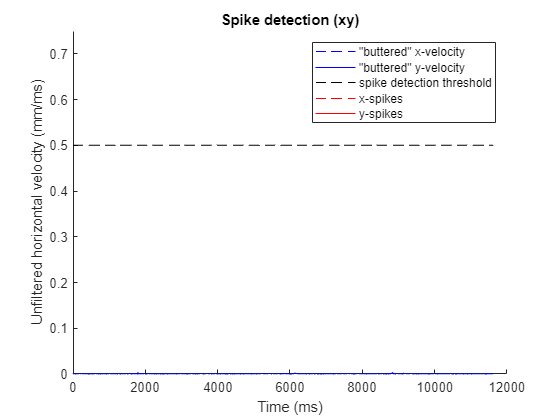

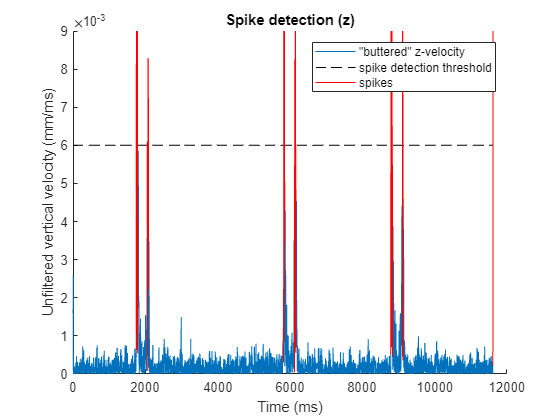

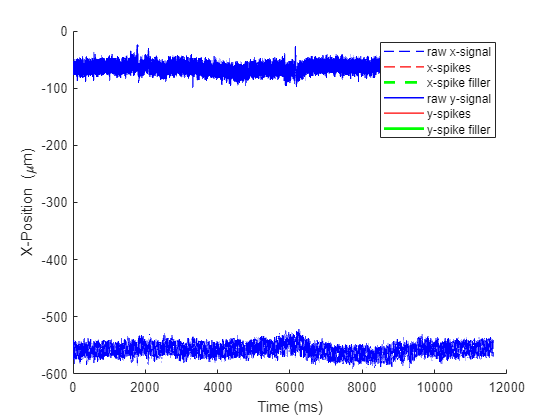

    drawplot = true;
    [x_pos,y_pos,z_pos, markfordeletion, mark_spikes_xy, mark_spikes_z] = clean_spikes(times_ms,x_pos,y_pos,z_pos, mode_rawdata, drawplot);

## ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

~~~~ NORMALIZE COIL VOLTAGES ~~~~ ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ Process coil voltages so that we have: - V_coilX (raw voltages, from file) - V_normX (voltage ratio, which appears as a normalized step function) - V_filX (filtered voltages, which show overall scale without PID fluctuations getting in the way) - i_newratio (1 where coil ratio changes, 0 otherwise) - PID_scaling (V_coilX/V_normX, in VOLTS, including rapid fluctuations

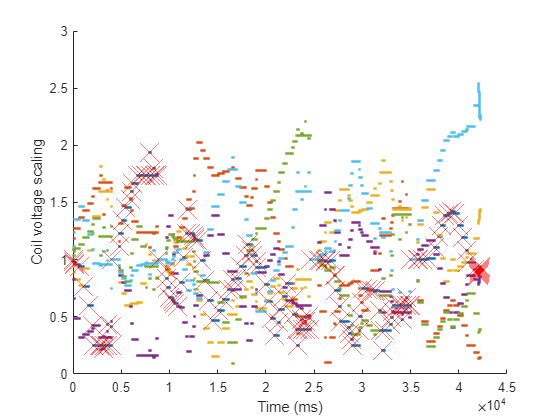

    % V_normX : Normalized V1x6 ratio
    V_coils = [V_coil1, V_coil2, V_coil3, V_coil4, V_coil5, V_coil6];
    V_coils_mean = sum(V_coils, 2) / 6;
    V_norm1 = V_coil1 ./ V_coils_mean;
    V_norm2 = V_coil2 ./ V_coils_mean;
    V_norm3 = V_coil3 ./ V_coils_mean;
    V_norm4 = V_coil4 ./ V_coils_mean;
    V_norm5 = V_coil5 ./ V_coils_mean;
    V_norm6 = V_coil6 ./ V_coils_mean;
    
    % V_filX : Filtered voltages (V)
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    lowpass_cutoff_V_hz = 0.016;
    [V_fil1,~] = filter_lowpass(times_ms,V_coil1,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    [V_fil2,~] = filter_lowpass(times_ms,V_coil2,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    [V_fil3,~] = filter_lowpass(times_ms,V_coil3,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    [V_fil4,~] = filter_lowpass(times_ms,V_coil4,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    [V_fil5,~] = filter_lowpass(times_ms,V_coil5,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    [V_fil6,~] = filter_lowpass(times_ms,V_coil6,0,lowpass_cutoff_V_hz,filtershape,1,'Low-pass');
    
    % i_newratio : Row indices where new coil ratio is introduced
    V_norms = [V_norm1, V_norm2, V_norm3, V_norm4, V_norm5, V_norm6];
    V_norms_shifted = circshift(V_norms,1,1);
    i_newratio     = sum(abs(V_norms - V_norms_shifted) > 1e-10,2) ~= 0;         % "1" where the coil ratio changes, "0" otherwise
    i_newratio(1) = 1;
    i_newratio_nan = double(i_newratio);
    i_newratio_nan(~i_newratio) = NaN;                                           % "1" where the coil ratio changes, "NaN" otherwise

    % PID scalings
    % PID_scaling = V_coil1 ./ V_norm1;    % In VOLTS; includes rapid fluctuations
    PID_scaling = mean([V_coil1 ./ V_norm1,V_coil2 ./ V_norm2,V_coil3 ./ V_norm3,V_coil4 ./ V_norm4,V_coil5 ./ V_norm5,V_coil6 ./ V_norm6],2);



    % ----------------- Plot --------------------
    close all
    figure;

    % Left axis v2: Time vs NORMALIZED Voltages
    % yyaxis left
    hold on
    plot(times_ms, V_norm1, '.');
    % plot(times_ms, V_norm1.*i_newratio_nan, 'r.')
    plot(times_ms, V_norm2, '.');
    plot(times_ms, V_norm3, '.');
    plot(times_ms, V_norm4, '.');
    plot(times_ms, V_norm5, '.');
    plot(times_ms, V_norm6, '.');
    scatter(times_ms, V_norm1.*i_newratio_nan, 400, 'rX')
    hold off
    ylabel("Coil voltage scaling")

    % Labels and legend
    xlabel("Time (ms)")

## (Display where new ratios occurred)

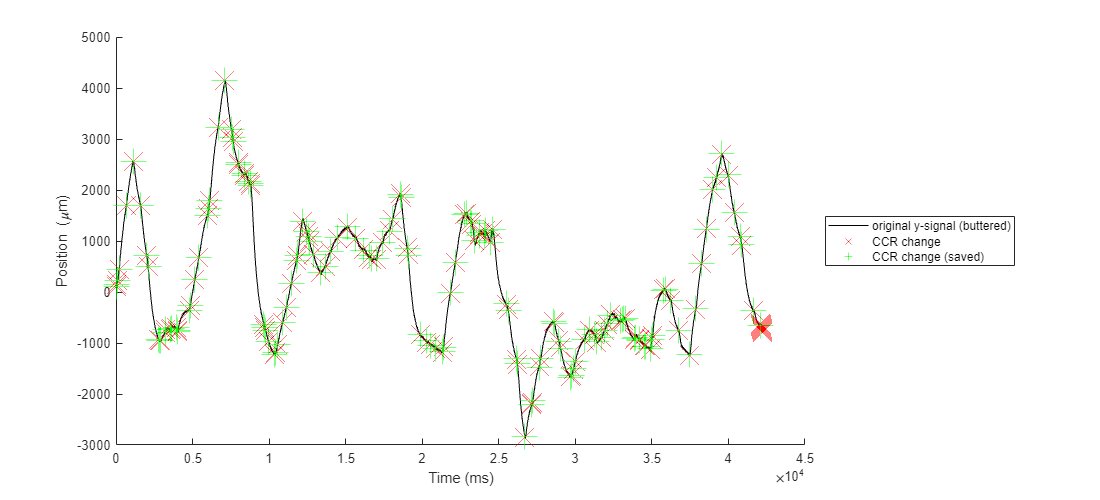

    % (Ver 1: new ratio vs time)
    % figure
    % hold on
    % plot(i_newratio,'DisplayName','bool')
    % scatter(times_ms,i_newratio_nan,'DisplayName','nanversion')
    % hold off
    % legend()
    
    % ver 2: track position
        % (TEMP) Read ttable, to check where the new CCR indices were
        % actually tracked
            load('alldata.mat')
            ttable_saved = ttable(ttable.filename_indices == mf4_filename_index,:);
            i_newratio_saved = zeros(size(times_ms));
            i_newratio_saved(1) = 1; i_newratio_saved(ttable_saved.timestamp_starts+1) = 1;
            i_newratio_saved_nan = double(i_newratio_saved);
            i_newratio_saved_nan(~i_newratio_saved) = NaN;

        % Figure window size
        figwidth_px = 1100; 
        figheight_px = 500;
        figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];
        % xlim([end-10000,end])
        xlabel("Time (ms)")
        
        % Left axis: positions
        hold on
        plot(times_ms,y_pos*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','original y-signal (buttered)');
        scatter(times_ms, y_pos*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
        scatter(times_ms, y_pos*1000.*i_newratio_saved_nan, 400, 'g+','DisplayName','CCR change (saved)');
        % plot(times_ms,y_fil*1000 , 'Color',[0, 1, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','buttered -> 100Hz resamp -> ??? (final)');
        % scatter(times_ms, y_fil*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
        % scatter(times_ms, y_fil*nan.*i_newratio_nan, 400, 'bX','DisplayName','Potential accel. disagreement');
        hold off
        ylabel("Position (\mum)")        

        if figwidth_px >= figheight_px*1.5
            legend_position = "eastoutside";
        elseif figheight_px >= figwidth_px*1.5
            legend_position = "southoutside";
        else
            legend_position = "best";
        end
        
        legend("Location",legend_position);

## ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

~~~~ CALCULATE "FORCES"  ~~~~ ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

    disp("Reminder: Loop through 'segments'. For each segment, find start/finish points and start/finish velocities!")

Reminder: Loop through 'segments'. For each segment, find start/finish points and start/finish velocities!


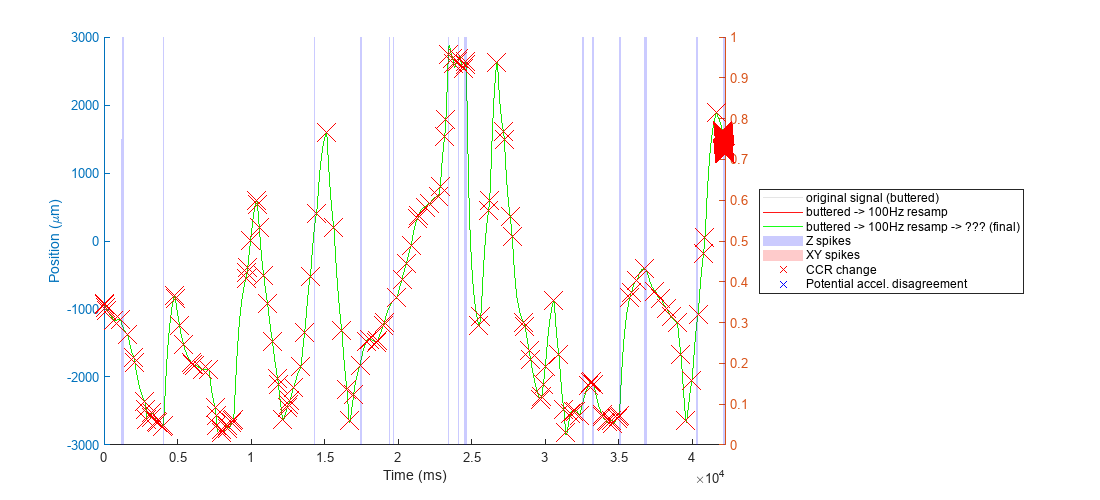


    % mode_accel_method = "continuous"
    drawplot = 2;
    idx_to_draw = 1;
    filterwidth = 0.035;
    savitzkywidth = 71;
    xrange = [10000,11000];     % "[nan,nan]" will give default min/max values
    % xrange = [3.43e4,3.53e4];     % "[nan,nan]" will give default min/max values
    xrange = [2.95e4,3.05e4];     % "[nan,nan]" will give default min/max values
    xrange = [nan,nan];     % "[nan,nan]" will give default min/max values
    close all

    if ismember(lower(mode_accel_method),["steps","chunks","segments"])
        % Separates the data into "segments". Accelerations are calculated
        % throughout each segment. The final result is a discontinuous
        % curve across all times.
        error("`mode_accel_calculation=='steps'` is unimplemented for position control.");   
    elseif ismember(lower(mode_accel_method),["steps-simple","simple"])
        % Separates the data into "segments". A single segment corresponds
        % to a single row in the final table. This leads to an extremely 
        % lightweight dataset for training, but assumes that the magnet 
        % moves in a straight line for each new coil current ratio-- 
        % which is not the case for most setups.  
    elseif lower(mode_accel_method)=="continuous"
        % Treats the full dataset as one segment. The final result is a
        % continuous acceleration curve across all times.
        error("`mode_accel_calculation=='continuous'` is unimplemented for position control.");   
        % i_newratio(:) = 0; i_newratio(1) = 1;
        % i_newratio_nan(:) = nan; i_newratio_nan(1) = 1;
    else
        error("Invalid `mode_accel_calculation`");
    end

    % Filter entire file at once (x,y,z)
    [x_fil, y_fil, z_fil] = filterdata(times_ms,x_pos,y_pos,z_pos,...
                                       mode_rawdata,filterwidth,savitzkywidth,markfordeletion,...
                                       str_fname,drawplot,xrange);
    % Draw filtered position data
    if drawplot
        plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2], "Z spikes");
        plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2], "XY spikes");
        hold on
        yyaxis left
        scatter(times_ms, x_fil*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
        scatter(times_ms, x_fil*nan.*i_newratio_nan, 400, 'bX','DisplayName','Potential accel. disagreement');
        % yyaxis right
        hold off
    end

Elapsed time is 1.637974 seconds.
Exponential Fit Goodness of Fit:
           sse: 1.4635
       rsquare: 0.51539
           dfe: 49
    adjrsquare: 0.49561
          rmse: 0.17282
Decaying Sinusoidal Fit Goodness of Fit:
           sse: 0.0095863
       rsquare: 0.99683
           dfe: 47
    adjrsquare: 0.99656
          rmse: 0.014282
OBVIOUS OSCILLATION DETECTED


relative_accel_expo =        10.513

relative_accel_sine =        7.5368

FINAL SELECTION REPORT: Obvious oscillation detected


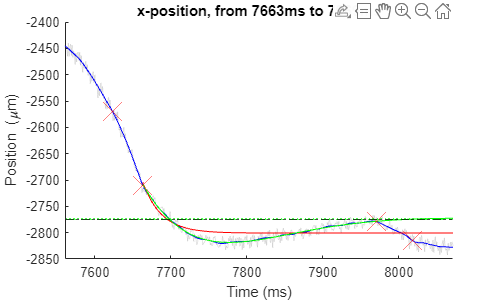


    % Define "segments" based on `mode_accel_method`
    new_ccr_indices = find(i_newratio);         % Indices of all distinct CCRs
    num_ccr_indices = length(new_ccr_indices);  % Total number of distinct CCRs in file

    % Initialize final outputs
    len = length(times);    % Number of entries in file
    x_starts = nan(num_ccr_indices,1);
    x_finals = nan(num_ccr_indices,1);
    x_velocs = nan(num_ccr_indices,1);  % Initial velocities
    y_starts = nan(num_ccr_indices,1);
    y_finals = nan(num_ccr_indices,1);
    y_velocs = nan(num_ccr_indices,1);  % Initial velocities
    V_segs_1 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    V_segs_2 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    V_segs_3 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    V_segs_4 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    V_segs_5 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    V_segs_6 = nan(num_ccr_indices,1);  % Normalized coil current (per segment)
    filename_indices  = nan(num_ccr_indices,1);   % .mf4 file index (e.g. 17 for "_0017.mf4")
    timestamp_starts = nan(num_ccr_indices,1);   % Timestamp for recording start (e.g. 15223 for a recording starting at 15222.9123ms)
    deleteflag       = nan(num_ccr_indices,1);   % Flag for deleting a row, if needed
    % disp("Reminder: The initial velocities are VERY VERY APPROXIMATE, and should be disregarded if possible since extensive filtering is needed!")
    % disp("Reminder: The final positions are approximate, since the magnet has not actually stopped moving yet!")
        x_vel = gradient(x_fil, times_s);
        y_vel = gradient(y_fil, times_s);
        z_vel = gradient(z_fil, times_s);

    % if drawplot && ccr_idx==idx_to_draw
    %     disp("Segment "+num2str(ccr_idx)+": "+num2str(idx_start)+" to "+num2str(idx_end));
    %     plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2], "Z spikes");
    %     plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2], "XY spikes");
    %     hold on
    %     yyaxis left
    %     scatter(times_ms, x_fil(indices)*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
    %     scatter(times_ms, x_fil(indices)*nan.*i_newratio_nan, 400, 'bX','DisplayName','Potential accel. disagreement');
    %     % yyaxis right
    %     hold off
    % end

    % Gather final outputs
    % for ccr_idx=6:num_ccr_indices
    for ccr_idx=31:num_ccr_indices
    % for ccr_idx=drawsegment
        idx_start = new_ccr_indices(ccr_idx);   % Start of "segment"
        if ccr_idx~=num_ccr_indices 
            idx_end = new_ccr_indices(ccr_idx+1)-1; % End of "segment"
        else 
            idx_end = len; 
        end
    
        indices = idx_start:idx_end;

        % check if segment is unusably short
        seg_minimumduration_ms = 5;
        tooshort = (idx_end - idx_start) < seg_minimumduration_ms;

        % try
        x_starts(ccr_idx) = x_fil(idx_start);
        x_velocs(ccr_idx) = x_vel(idx_start);
        y_starts(ccr_idx) = y_fil(idx_start);
                x_finals(ccr_idx) = x_fil(idx_end);
                y_finals(ccr_idx) = y_fil(idx_end);


                % !!!!!!!!!!!!! Exponential extrapolation to find "end" points!
                % STEPS:
                % 1. FIT A CURVE TO THE WHOLE "SEGMENT"
                % 2. IF THE "SEGMENT" CANNOT BE FIT TO A CURVE, THEN USE THE FAR
                % END OF THE CURVE ONLY!
                verbose = true;
                
                
                plotnprompt = true;
                [t_fit_x, x_expofit, x_sinefit, x_final_expo, x_final_sine, x_final_sin_firstv0, x_finalselection] = xy_find_finals(times_ms(indices),x_fil(indices),verbose,extrap_mode);

                % ALSO: For now, plot the curve with window focused on the
                % segment, and overlay the "fitted" curve (ending at
                % velocity=0). Request user input each time so I can see
                % the result before continuing the loop!
                if plotnprompt
                    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~
                    % ~~~~ SHOW RESULTS FOR X ~~~~
                    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~
                    % Define data
                    hmode = "x";
                    raw = x_pos;
                    fil  = x_fil;
                    t_fit = t_fit_x;
                    expofit = x_expofit;
                    sinefit = x_sinefit;
                    final_expo = x_final_expo;
                    final_sine = x_final_sine;
                    final_sine_firststop = x_final_sin_firstv0;
                    final_selection = x_finalselection;

                    % Actual plot (copy-pasteable below this line)
                    % window range
                    xmin = times_ms(idx_start) - length(indices)/3;
                    xmax = times_ms(idx_end) + length(indices)/3;
                    % Figure window size
                    figwidth_px = 500; 
                    figheight_px = 300;
                    close; figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];
                    xlim([xmin,xmax])
                    xlabel("Time (ms)")
                    
                    % Left axis: positions
                    hold on
                    patchline(times_ms,raw*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','original signal (buttered)');
                    plot(times_ms,fil*1000 , 'Color',[0, 0, 1, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','buttered -> 100Hz resamp -> ??? (final)');
                    plot(t_fit, expofit*1000, 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', ...
                        'DisplayName','fitted expo curve for Segment '+string(ccr_idx));
                    if abs(final_expo - expofit(end)) < (expofit(end) - expofit(1))*2
                        yline(1000*final_expo, 'r--', 'DisplayName','Expo fit inf. limit'); % Skip if it's way out of range
                    end
                    plot(t_fit, sinefit*1000, 'Color',[0, 1, 0, 0.9],'LineWidth',0.1,'LineStyle','-', ...
                        'DisplayName','fitted decaying-sinuses curve for Segment '+string(ccr_idx));
                    yline(1000*final_sine, 'g--', 'DisplayName','Sine fit inf. limit'); 
                    yline(1000*final_sine_firststop, 'g:', 'DisplayName','Sine fit first v=0'); 
                    yline(1000*final_selection, 'k-.', 'DisplayName','final choice'); 

                    scatter(times_ms, fil*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
                    plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2], "Z spikes");
                    plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2], "XY spikes");
                    hold off
                    ylabel("Position (\mum)")
                    % legend_position = "best"; legend("Location",legend_position);

                    title(hmode+"-position, from "+string(round(times_ms(indices(1))))+"ms to "+string(round(times_ms(indices(end))))+"ms")

                    input("ccr_idx = "+string(ccr_idx)+", hmode="+hmode+". Input anything to continue, or CTRL+C to exit.")
                end

                [t_fit_y, y_expofit, y_sinefit, y_final_expo, y_final_sine, y_final_sin_firstv0, y_finalselection] = xy_find_finals(times_ms(indices),y_fil(indices),verbose,extrap_mode);
                if plotnprompt
                    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~
                    % ~~~~ SHOW RESULTS FOR Y ~~~~
                    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~
                    % Define data
                    hmode = "y";
                    raw = y_pos;
                    fil  = y_fil;
                    t_fit = t_fit_y;
                    expofit = y_expofit;
                    sinefit = y_sinefit;
                    final_expo = y_final_expo;
                    final_sine = y_final_sine;
                    final_sine_firststop = y_final_sin_firstv0;
                    final_selection = y_finalselection;

                    % Actual plot (copy-pasteable below this line)
                    % window range
                    xmin = times_ms(idx_start) - length(indices)/3;
                    xmax = times_ms(idx_end) + length(indices)/3;
                    % Figure window size
                    figwidth_px = 500; 
                    figheight_px = 300;
                    close; figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];
                    xlim([xmin,xmax])
                    xlabel("Time (ms)")
                    
                    % Left axis: positions
                    hold on
                    plot(times_ms,raw*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','original signal (buttered)');
                    plot(times_ms,fil*1000 , 'Color',[0, 0, 1, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','buttered -> 100Hz resamp -> ??? (final)');
                    plot(t_fit, expofit*1000, 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', ...
                        'DisplayName','fitted expo curve for Segment '+string(ccr_idx));
                    if abs(final_expo - expofit(end)) < (expofit(end) - expofit(1))*2
                        yline(1000*final_expo, 'r--', 'DisplayName','Expo fit inf. limit'); % Skip if it's way out of range
                    end
                    plot(t_fit, sinefit*1000, 'Color',[0, 1, 0, 0.9],'LineWidth',0.1,'LineStyle','-', ...
                        'DisplayName','fitted decaying-sinuses curve for Segment '+string(ccr_idx));
                    yline(1000*final_sine, 'g--', 'DisplayName','Sine fit inf. limit'); 
                    yline(1000*final_sine_firststop, 'g:', 'DisplayName','Sine fit first v=0'); 
                    yline(1000*final_selection, 'k-.', 'DisplayName','final choice'); 

                    scatter(times_ms, fil*1000.*i_newratio_nan, 400, 'rX','DisplayName','CCR change');
                    plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2], "Z spikes");
                    plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2], "XY spikes");
                    hold off
                    ylabel("Position (\mum)")
                    % legend_position = "best"; legend("Location",legend_position);

                    title(hmode+"-position, from "+string(round(times_ms(indices(1))))+"ms to "+string(round(times_ms(indices(end))))+"ms")

                    input("ccr_idx = "+string(ccr_idx)+", hmode="+hmode+". Input anything to continue, or CTRL+C to exit.")
                end




        y_velocs(ccr_idx) = y_vel(idx_start);
        V_segs_1(ccr_idx) = V_norm1(idx_start);
        V_segs_2(ccr_idx) = V_norm2(idx_start);
        V_segs_3(ccr_idx) = V_norm3(idx_start);
        V_segs_4(ccr_idx) = V_norm4(idx_start);
        V_segs_5(ccr_idx) = V_norm5(idx_start);
        V_segs_6(ccr_idx) = V_norm6(idx_start);
        filename_indices(ccr_idx)  = mf4_filename_index;
        timestamp_starts(ccr_idx) = round(times_ms(idx_start));
        deleteflag(ccr_idx)       = tooshort;
        % catch
        %     disp("Segment "+num2str(idx)+": "+num2str(idx_start)+" to "+num2str(idx_end));
        %     disp("           Acceleration calculation failed.")
        % end
    end

## ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

~~~~ FINALIZE TABLE ~~~~ ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


    
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    % ~~~~ CREATE MORE ORGANIZED TABLE ~~~~
    % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    % disp("Reminder: The lightweight-accel version should insta-delete the overwhelming majority of the rows in the table!")
    disp("Reminder: The lightweight-accel version should also have corresponding indicators of power requirements and heat generation (see Trello), so that each entry can be weighted.")

Reminder: The lightweight-accel version should also have corresponding indicators of power requirements and heat generation (see Trello), so that each entry can be weighted.


    
    % "Continuous" data (UNUSED FOR POSITION CONTROL)
    % data = timetable(times, V_coil1, V_coil2, V_coil3, V_coil4, V_coil5, V_coil6, ...
    % V_fil1, V_fil2, V_fil3, V_fil4, V_fil5, V_fil6, ...
    % PID_scaling, ...
    % x_pos, y_pos, z_pos, ...
    % x_fil, y_fil, z_fil, ...
    % x_vel, y_vel, z_vel, ...
    % x_acc, y_acc, z_acc);

    % "Simple" (segmented) data, for position control
    data = table(x_starts,y_starts,x_finals,y_finals, ...
                x_velocs,y_velocs, ...
                V_segs_1, V_segs_2, V_segs_3, V_segs_4, V_segs_5, V_segs_6, ...
                filename_indices,timestamp_starts);
    
    % ~~~~~~~~~~~~~~~~~~~~~~~
    % ~~~~ FINAL TOUCHES ~~~~
    % ~~~~~~~~~~~~~~~~~~~~~~~
    disp("Reminder: Here, track power cost and heat generation throughout. Remove lowest-weight data for the non-lightweight-accel versions, to improve training speeds.")

Reminder: Here, track power cost and heat generation throughout. Remove lowest-weight data for the non-lightweight-accel versions, to improve training speeds.


    % disp("Reminder: CHANGES TO MAKE: Only use the `markfordeletion` bit for completely unsalvageable data; we want to properly weight the data instead!")
        % ^ ("Completely unsalvageable data" includes data where at least 1 sensor is empty, erroneous PID_scaling==0/NaN cases, coil saturation reached, etc)
    
    
    
    
    % DELETE ALL ROWS WITH INVALID DATA

    % (OLD) Time-domain table
        % % delete data close to where the spikes were
        % % markfordeletion = markfordeletion;
        % 
        % % % |dz| > threshold
        % % % (Temporary, until I can account for height!)
        % % z_target_mm = 2.00;             % ensure same units as z_pos
        % % dz = abs(z_target_mm - z_pos);
        % % markfordeletion = markfordeletion | (dz > 0.1);
        % 
        % % Problematic diagnostics
        % % markfordeletion = markfordeletion | diagnostics_z_resting_toolow | ...
        % %     diagnostics_head1_empty | diagnostics_head2_or_head3_empty | ...
        % %     diagnostics_head1_off | diagnostics_head2_off | diagnostics_head3_off;
        % markfordeletion = markfordeletion | ~diagnostics_is_ready_to_run | ...
        %     (abs(x_pos) > 5.0) | (z_pos < -1) | isnan(PID_scaling);
    
    % (NEW) Row by row
    rows_to_delete = find(deleteflag);
    
    % Apply deletion
    data(rows_to_delete,:) = [];
    
    
    % % RANDOMLY SELECT ~5% OF DATASET, AND KEEP IT!
    % idx_keep = randperm(height(data));
    % file_data = data(idx_keep(1:round(height(data)*data_keep_ratio)),:);

    file_data = data;
    % % ^ Final set of data from this file. Append onto the main table, and move
    % % on to the next file!

## Functions (+Testing)

## test

    movingwindow_threshold_ms = 100;
    PIDjitter_threshold_V = 0.02;
    movingmax = movmax(PID_scaling,[movingwindow_threshold_ms, 20]);
    movingmin = movmin(PID_scaling,[movingwindow_threshold_ms, 20]);
    mark_PIDjitter = abs(movingmax - movingmin) > PIDjitter_threshold_V;

    figure;
    yyaxis left
    hold on
    plot(times_ms, z_pos)
    plot_highlight_regions(times_ms, mark_PIDjitter)
    hold off
    
    yyaxis right
    hold on
    plot(times_ms, PID_scaling)
    plot(times_ms, movingmax)
    plot(times_ms, movingmin)
    hold off
    
    % xlim([3.5e4,3.7e4])
    xlim([0.5e4,1e4])

xlim([8729 13729])

## Compare "continuous" calculation to "step" calculation

% "Continuous" calculation
x_acc_cont = nan(len,1);
y_acc_cont = nan(len,1);
z_acc_cont = nan(len,1);
x_fil_cont = nan(len,1);     % Filtered position (for visualization)
y_fil_cont = nan(len,1);
z_fil_cont = nan(len,1);
indices = 1:len;
[x_acc_cont(indices), y_acc_cont(indices), z_acc_cont(indices), ...
 x_fil_cont(indices), y_fil_cont(indices), z_fil_cont(indices)] = filterdata(times_ms(indices), ...
                                                     x_pos(indices),y_pos(indices),z_pos(indices), ...
                                                     mode_rawdata,filterwidth,0);

    
% Visualize (one axis at a time)
close all; figure;

% Left axis: positions
yyaxis left
hold on
plot(times_ms,x_pos*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','original signal');
plot(times_ms,x_fil_cont*1000, 'Color',[0, 0, 0.8, 0.1],'LineWidth',0.1,'LineStyle','--', 'DisplayName','signal (continuous)');
plot(times_ms,x_fil*1000, 'Color',[0.7, 0, 0.8, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','signal (discont.)');
scatter(times_ms, x_pos*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio')
hold off
plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2], "Z spikes");
plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2], "XY spikes");
ylabel("Position (\mum)")


% Right axis: accelerations
yyaxis right
hold on
plot(times_ms,x_acc_cont*1000, 'Color',[0.9, 0.3, 0., 1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acceleration (continuous)');
plot(times_ms,x_acc*1000, 'Color',[0.3, 0.8, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acceleration (discont.)');
scatter(times_ms, x_acc*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio','HandleVisibility','off')
patchline(times_ms,times_ms*0, 'Color',[0,0,0, 0.2],'LineWidth',0.5,'LineStyle','--', 'HandleVisibility','off');
hold off
legend("Location","eastoutside");
ylabel("Acceleration (\mum/s/s)")
% ylim([-1500,2000])
xlim([29000,31000])
% xlim([xmin,xmax])
xlabel("Time (ms)")
fig=gcf;
fig.Position(3:4)=[800,400];

disp("Note: We expect the `continuous` and `discont.` filtered signals to overlap with the original signal almost perfectly. If this is not the case, something terrible has happened!")

function [x_fil, y_fil, z_fil] = filterdata(times_ms, x_pos, y_pos, z_pos, mode_rawdata, filterwidth, savitzkywidth, markfordeletion, str_fname, drawplot, xrange)
% Filter signals.
% NOTE: When using Fourier filters (`ifilter_noplot`), the filtered signal
%   be inaccurate towards the start & ends, with these inaccurate regions
%   widening _inversely_ to filter width (i.e. lower filter width = wider
%   inaccurate region), and apparently NOT being affected by total signal
%   duration (i.e. a ~1.5s inaccurate region will be 1.5s on all
%   recordings!).
% Smooth tapering, signal padding, or _signal "cropping"_ is needed.
%
% Note: Setting `drawplot==0` does not plot. Setting `drawplot==1` simply
% plots filtered position and final acceleration. Setting `drawplot==2`
% displays a more detailed filter analysis.
    xmin = nanmax(xrange(1),times_ms(1));
    xmax = nanmin(xrange(2),times_ms(end));
    times_s = times_ms/1000;

    % ~~~~~~~~~~~~~~~~~~~~~
    % ~~~~~ FILTERING ~~~~~
    % ~~~~~~~~~~~~~~~~~~~~~

    % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(10ms)),
    % to keep filter behaviour consistent between `mode_rawdata` settings
    if lower(mode_rawdata)=="raw"
        simulink_mavge_ms = 10;
        [bee,aye] = butter(6, 0.6);
        x_pos = movmean(filtfilt(bee,aye,x_pos), simulink_mavge_ms);
        y_pos = movmean(filtfilt(bee,aye,y_pos), simulink_mavge_ms);
        z_pos = movmean(filtfilt(bee,aye,z_pos), simulink_mavge_ms);
    end

    % FILTER 1 : `Resampling filter` to eliminate 100Hz noise!
    x_pos_resamp = resampling_filter(times_s, x_pos,100);
    y_pos_resamp = resampling_filter(times_s, y_pos,100);
    z_pos_resamp = resampling_filter(times_s, z_pos,100);
        x_fil = x_pos_resamp;
        y_fil = y_pos_resamp;
        z_fil = z_pos_resamp;

    % % FILTER 2 : S-G polyfit
    % noise_period_ms = savitzkywidth;
    % x_sgfilt = sgolayfilt(x_pos_resamp,2,noise_period_ms);
    % y_sgfilt = sgolayfilt(y_pos_resamp,2,noise_period_ms);
    % 
    % % FILTER 3 : Low-pass
    % lowpass_cutoff_hz = filterwidth;
    % filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    % [x_fil,~] = filter_lowpass(times_ms,x_sgfilt,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');
    % [y_fil,~] = filter_lowpass(times_ms,y_sgfilt,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');
    

    % CHECK FILTERED DATA FOR 'DISAGREEMENTS'!
        toosudden_threshold_micron = 20; % In µm
        toosudden_idx = (abs(x_fil - x_pos)*1000 >= toosudden_threshold_micron) + ...
                        (abs(y_fil - y_pos)*1000 >= toosudden_threshold_micron);
        toosudden_idx = logical(toosudden_idx);
        toosudden_idx = toosudden_idx & not(markfordeletion);   % Ignore data that'll be removed anyways
        
        % Warn wherever disagreements occur!
        transitions = diff([0, toosudden_idx', 0]);  % Nonzero wherever a cluster of 1's begins or ends
        cluster_starts = find(transitions == 1);
        cluster_ends   = find(transitions == -1) - 1;
        cluster_centers = round((cluster_starts + cluster_ends) / 2);
        if sum(toosudden_idx)~=0
            fprintf('WARNING: File `_00%d.mf4` filters failed to match raw data near timestamps (in ms):', parse_mf4_number(str_fname));
            fprintf('%d ',round(times_ms(cluster_centers)));
        end
  

    % ~~~~~~~~~~~~~~~~~~~~
    % ~~~~~ PLOTTING ~~~~~
    % ~~~~~~~~~~~~~~~~~~~~
    if drawplot>0
        % Figure window size
        figwidth_px = 1100; 
        figheight_px = 500;
        figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];
        xlim([xmin,xmax])
        xlabel("Time (ms)")
        
        % Left axis: positions
        yyaxis left
        hold on
        plot(times_ms,x_pos*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','original signal (buttered)');
        plot(times_ms,x_pos_resamp*1000 , 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','buttered -> 100Hz resamp');
        plot(times_ms,x_fil*1000 , 'Color',[0, 1, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','buttered -> 100Hz resamp -> ??? (final)');
        hold off
        ylabel("Position (\mum)")


        % % Right axis: accelerations
        % yyaxis right
        % ylabel("Acceleration (\mum/s/s)")
        % hold on
        % patchline(times_ms,times_ms*0, 'Color',[0,0,0, 0.2],'LineWidth',0.5,'LineStyle','--', 'HandleVisibility','off');
        
        % % TEST OUT FILTER WIDTHS (if specified)
        % if drawplot>1
        %     % Select frequency ranges to plot
        %     test_frequencies = 0.020:0.002:0.080;
        %     alpha_start = 0.25;
        %     alpha_end = 0.05;
        % 
        %     displaystring = "-";
        %     for test_frequency=test_frequencies
        %         index = find(test_frequencies==test_frequency);
        %         set_alpha =   alpha_start + (alpha_end-alpha_start) * ((index-1) / max(1,numel(test_frequencies)-1));
        % 
        %         % Piecewise plotting settings (format: freq_display_settings = [maxfreq, R, G, B, Alpha;
        %         %                                                               maxfreq2,R2,G2,B2,Alpha2]
        %         freq_display_settings = [0.024, rgb(244, 67, 54), set_alpha; % Minimum freq is 0 for first row
        %                                  0.032, rgb(156, 39, 176), set_alpha;
        %                                  0.040, rgb(33, 150, 243), set_alpha;
        %                                  0.048, rgb(76, 175, 80), set_alpha;
        %                                  0.056, rgb(255, 87, 34), set_alpha;
        %                                  0.080, rgb(141, 110, 99), set_alpha*0.5];
        %         % Get colour+alpha based on frequency
        %         freqs = freq_display_settings(:,1); n_decimals = numdecpoints(freqs);
        %         band = sum(test_frequency > freqs)+1;   % The row of `freq_display_settings` that test_frequency falls into
        %         if band==1 minfreq=min(test_frequencies); else minfreq=freq_display_settings(band-1,1); end
        %         maxfreq = freq_display_settings(band,1);
        %         colour = freq_display_settings(band,2:end);
        %         displaystring_prev = displaystring;
        %         displaystring      = num2str(minfreq,"%."+num2str(n_decimals)+"f")+"-"+num2str(maxfreq,"%."+num2str(n_decimals)+"f")+"Hz lowpass accel";
        %         flag_newband = displaystring~=displaystring_prev;
        % 
        %         % Actually plot now!
        %         [x_fil_00X,~] = filter_lowpass(times_ms,x_sgfilt,0,test_frequency,filtershape,1,'Low-pass');
        %         x_vfil_00X = gradient(x_fil_00X, times_s);
        %         x_afil_00X = gradient(x_vfil_00X, times_s);
        %         patchline(times_ms,x_afil_00X*1000, 'Color',[colour],'LineWidth',2,'LineStyle','-', 'DisplayName', ...
        %             num2str(test_frequency,"%."+num2str(n_decimals)+"f")+"Hz lowpass accel",'HandleVisibility','off');
        %         if flag_newband
        %             patchline(times_ms,x_afil_00X*nan, 'Color',[colour(1:3),colour(4)*2],'LineWidth',2,'LineStyle','-', 'DisplayName', displaystring,'HandleVisibility','on');    
        %         end
        %     end
        % end
        
        
        % "Comparison" position+acceleration(s) (as many as needed)
        % test_frequency = filterwidth;
        % [x_fil_final,~] = filter_lowpass(times_ms,x_sgfilt,0,test_frequency,filtershape,1,'Low-pass');
        % x_vfil_final = gradient(x_fil_final, times_s);
        % x_afil_final = gradient(x_vfil_final, times_s);
        % 
        % yyaxis left
        % plot(times_ms,x_fil_final*1000, 'Color',[0, 0.7, 0.1, 0.99],'LineWidth',1,'LineStyle','-', 'DisplayName',num2str(test_frequency)+"Hz lowpass position (final?)");
        % yyaxis right
        % patchline(times_ms,x_afil_final*1000, 'Color',[0., 0.9, 0.5, 1],'LineWidth',1,'LineStyle','-', 'DisplayName', num2str(test_frequency)+"Hz lowpass accel (final?)");

    
        % test_frequency = 0.03;
        % [x_fil_final,~] = filter_lowpass(times_ms,x_sgfilt2,0,test_frequency,filtershape,1,'Low-pass');
        % x_vfil_final = gradient(x_fil_final, times_s);
        % x_afil_final = gradient(x_vfil_final, times_s);
        % patchline(times_ms,x_afil_final*1000, 'Color',[0., 0.9, 0, 1],'LineWidth',0.5,'LineStyle','-', 'DisplayName', num2str(test_frequency)+"Hz lowpass accel (test)");
        % 
        % test_frequency = 0.045;
        % [x_fil_final,~] = filter_lowpass(times_ms,x_sgfilt2,0,test_frequency,filtershape,1,'Low-pass');
        % x_vfil_final = gradient(x_fil_final, times_s);
        % x_afil_final = gradient(x_vfil_final, times_s);
        % patchline(times_ms,x_afil_final*1000, 'Color',[0.9, 0.9, 0, 1],'LineWidth',0.5,'LineStyle','-', 'DisplayName', num2str(test_frequency)+"Hz lowpass accel (test)");
        
        hold off
        if figwidth_px >= figheight_px*1.5
            legend_position = "eastoutside";
        elseif figheight_px >= figwidth_px*1.5
            legend_position = "southoutside";
        else
            legend_position = "best";
        end
        
        legend("Location",legend_position);
    end
end



function [x_acc, y_acc, z_acc] = get_accelerations_legacy(times_ms, x_pos, y_pos, z_pos, drawplot)
% Filter signals.
% NOTE: When using Fourier filters (`ifilter_noplot`), the filtered signal
%   be inaccurate towards the start & ends, with these inaccurate regions
%   widening _inversely_ to filter width (i.e. lower filter width = wider
%   inaccurate region), and apparently NOT being affected by total signal
%   duration (i.e. a ~1.5s inaccurate region will be 1.5s on all
%   recordings!).
% Smooth tapering, signal padding, or _signal "cropping"_ is needed.

            % % ~~ (UNUSED; less robust) POSITION FILTER ~~
            % % ALT FILTER 1 : Butterworth
            % fc = 3.1;    % Cutoff frequency (Hz)
            % fs = 1000;  % Sampling frequency (Hz)
            % n_order = 4; % Filter order (higher = steeper filter roll-off, but higher risk of phase distortion)
            % [bee,aye] = butter(n_order,fc/(fs/2));
            % x_fil2 = filtfilt(bee,aye,x_pos);   % Filters the data forward and then back, which prevents the phase shifting
    times_s = times_ms/1000;

    % ~~ POSITION FILTER 0 ~~
    % FILTER 1 : Low-pass, to get rid of the most extreme data spikes
    % filterwidth   = 0.002;    % in Hz, I think (initial run, pre-3/12/24)
    % filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    % [x_fil,~] = filter_lowpass(times_ms,x_pos,0,filterwidth,filtershape,1,'Low-pass');
    % [y_fil,~] = filter_lowpass(times_ms,y_pos,0,filterwidth,filtershape,1,'Low-pass');
    % [z_fil,~] = filter_lowpass(times_ms,z_pos,0,filterwidth,filtershape,1,'Low-pass');
    
    % ~~ POSITION FILTER 1 : S-G to remove noise, then filter out oscillations
    % with Fourier filter
    % FILTER 1 : S-G -> moving average
    noise_period_ms = 135;
    % x_mavge = sgolayfilt(x_pos,1,noise_period_ms);
    x_sgfilt = sgolayfilt(x_pos,3,noise_period_ms);
    x_sgfilt2 = sgolayfilt(x_sgfilt,1,noise_period_ms);
    y_sgfilt = sgolayfilt(y_pos,3,noise_period_ms);
    y_sgfilt2 = sgolayfilt(y_sgfilt,1,noise_period_ms);
    
    % FILTER 2 : Low-pass
    lowpass_cutoff_hz_001 = 0.001;
    lowpass_cutoff_hz_002 = 0.002;  % REPLACE WITH `lowpass_cutoff_hz` IN ACTUAL FUNCTION
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [x_fil_001,~] = filter_lowpass(times_ms,x_sgfilt2,0,lowpass_cutoff_hz_001,filtershape,1,'Low-pass');
    [x_fil_002,~] = filter_lowpass(times_ms,x_sgfilt2,0,lowpass_cutoff_hz_002,filtershape,1,'Low-pass');
    [y_fil_002,~] = filter_lowpass(times_ms,y_sgfilt2,0,lowpass_cutoff_hz_002,filtershape,1,'Low-pass');
    
    % FINAL FILTER:
    % Calculate accelerations real quicky-like (in mm/s/s)
    x_vfil_001 = gradient(x_fil_001, times_s);
    x_afil_001 = gradient(x_vfil_001, times_s);
    x_vel = gradient(x_fil_002, times_s);
    x_afil_002 = gradient(x_vel, times_s);
    y_vel = gradient(y_fil_002, times_s);
    y_afil_002 = gradient(y_vel, times_s);
    % ^ !!! 3/18/24 - DECIDE HOW TO COMBINE THE ABOVE FILTERS (INCLUDING
    % "ORIGINAL") INTO THEIR FINAL FORM! (IF NECESSARY)
    
    % ~~ some placeholder for z i guess ~~
    % FILTER 1
    z_sgfilt = sgolayfilt(z_pos,1,noise_period_ms);
    % FILTER 2 : Low-pass (GENTLE, for actual movement)
    filterwidth   = 0.02;    % in Hz, I think
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [z_fil,~] = ifilter_noplot(times_ms,z_sgfilt,0,filterwidth,filtershape,1,'Low-pass');
    z_fil = z_fil';
    z_vel = gradient(z_fil, times_s);
    z_afil = gradient(z_vel, times_s);    
    
    x_acc = x_afil_002;
    y_acc = y_afil_002;
    z_acc = z_afil;

    % -----Visualize (one axis at a time)----
    if drawplot
        xmin = 25000;
        xmax = 35000;
        close all; figure;
        
        % Left axis: positions
        yyaxis left
        hold on
        plot(times_ms,x_pos*1000, 'Color',[0, 0, 0, 0.1],'LineWidth',1,'LineStyle','-', 'DisplayName','original signal');
        plot(times_ms,x_fil_001*1000, 'Color',[0, 0.5, 1, 0.91],'LineWidth',2,'LineStyle','-', 'DisplayName','S-G + mavge + 0.001Hz lowpass');
        plot(times_ms,x_fil_002*1000, 'Color',[0, 0.5, 1, 0.91],'LineWidth',1,'LineStyle','--', 'DisplayName','S-G + mavge + 0.002Hz lowpass');
        % plot(times_ms,x_butter3*1000, 'Color',[1, 0.5, 0, 0.91],'LineWidth',2,'LineStyle',':', 'DisplayName','Butter 3Hz');
        % plot(times_ms,x_butter1*1000, 'Color',[1, 0.5, 0, 0.91],'LineWidth',2,'LineStyle','--', 'DisplayName','Butter 1Hz');
        hold off
        ylabel("Position (\mum)")
        % ylim([-1500,2000])
        % 
        % Right axis: accelerations
        yyaxis right
        hold on
        % plot(times_ms,x_afil_001*1000, 'Color',[0.9, 0.3, 0, 0.91],'LineWidth',1,'LineStyle','-', 'DisplayName','0.001Hz lowpass accel');
        plot(times_ms,x_acc*1000, 'Color',[0.9, 0.3, 0, 0.91],'LineWidth',1,'LineStyle','--', 'DisplayName','selected accel');
        % legend("Location","best");
        
        % Test out more accelerations
        test_frequencies = 0.0005:0.0002:0.0170;
        alpha_start = 0.1;
        alpha_end = 0.1;
        for test_frequency=test_frequencies
            index = find(test_frequencies==test_frequency);
            set_alpha =   alpha_start + (alpha_end-alpha_start) * ((index-1) / max(1,numel(test_frequencies)-1));
            [x_fil_00X,~] = filter_lowpass(times_ms,x_sgfilt2,0,test_frequency,filtershape,1,'Low-pass');
            x_vfil_00X = gradient(x_fil_00X, times_s);
            x_afil_00X = gradient(x_vfil_00X, times_s);
            patchline(times_ms,x_afil_00X*1000, 'Color',[0.9, 0.3, 0, set_alpha],'LineWidth',1,'LineStyle','-', 'DisplayName', num2str(test_frequency)+"Hz lowpass accel");  
            % scatter(times_ms,x_afil_00X*1000,2, 'Color',[0.9, 0.3, 0], 'MarkerEdgeAlpha',0.01,'MarkerFaceAlpha',set_alpha,'DisplayName', num2str(test_frequency)+"Hz lowpass accel");    
        end
        
        hold off
        % legend("Location","best");
        ylabel("Acceleration (\mum/s/s)")
        % ylim([-1500,2000])
        xlim([xmin,xmax])
        xlabel("Time (ms)")
    end
end


function [x_filled,y_filled,z_filled, markfordeletion, mark_spikes_xy, mark_spikes_z] = clean_spikes(times_ms,x_pos,y_pos,z_pos, mode_rawdata, drawplot)
% Detects unwanted "spikes" in X, Y, and/or Z measurements due to erroneous
% laser sensor readings (e.g. lasers being reflected into the wrong sensor
% by a glossy magnet).
% Data with unwanted "XY" spikes will be deleted, and these gaps will be
% filled using autoregressive modelling (`fillgaps()`). These filled gaps
% will be marked so that they are not actually used in ML training.

    % Find "raw" velocities, purely for initial analysis
    if lower(mode_rawdata)=="raw"
        % Apply Butterworth -> movingmean filter to eliminate the harshest noise
        simulink_mavge_ms = 10;
        [bee,aye] = butter(6, 0.6);
        x_pos_simumean = movmean(filtfilt(bee,aye,x_pos), simulink_mavge_ms);
        y_pos_simumean = movmean(filtfilt(bee,aye,y_pos), simulink_mavge_ms);
        z_pos_simumean = movmean(filtfilt(bee,aye,z_pos), simulink_mavge_ms);
        z_resamp = resampling_filter(times_ms/1000, z_pos_simumean,100);  % Known 100Hz noise is eliminated
        x_vbuttered = gradient(x_pos_simumean, times_ms);
        y_vbuttered = gradient(y_pos_simumean, times_ms);
        z_vbuttered = gradient(z_resamp, times_ms);
    elseif lower(mode_rawdata)=="buttered"
        x_vbuttered = gradient(x_pos, times_ms);
        y_vbuttered = gradient(y_pos, times_ms);
        z_vbuttered = gradient(z_pos, times_ms);
    else
        error("clean_spikes() - Invalid `mode_rawdata`.")
    end
    
    
    % Mark where v > some threshold, in mm/ms (spikes)
        % % Old ver (pre-July2024)
        % if lower(mode_rawdata)=="raw"
        %     threshold_vel_z = 0.04;     % for "raw" z data
        %     threshold_vel_xy = 0.5;     % for "raw" xy data (Intentionally obscenely high)
        % elseif lower(mode_rawdata)=="buttered"
        %     threshold_vel_z = 0.005;     % for "buttered" z data
        %     threshold_vel_xy = 0.5;     % for "raw" xy data (Intentionally obscenely high)
        % else
        %     error("clean_spikes() - Invalid `mode_rawdata`.")
        % end

        % New ver (post-July2024)
        threshold_vel_z = 0.006;     % for "buttered" z data
        threshold_vel_xy = 0.5;     % for "raw" xy data (Intentionally obscenely high)
        mark_spikes_xy = (abs(x_vbuttered) > threshold_vel_xy) | (abs(y_vbuttered) > threshold_vel_xy);
        mark_spikes_z = abs(z_vbuttered) > threshold_vel_z;

        % Create "continuous" marked regions
        % (Note: The spikes typically last about ~100ms each)
        % (Note: This is done using image dilation, and assumes that the data was
        %    recorded periodically-- and if it wasn't, then something has already
        %    gone horribly wrong)
        nearspikes_threshold = 100;                 % closeness threshold, ms (approx)
        strel = ones(1+2*nearspikes_threshold,1);   % 1D structuring element
        strel_erode = ones(1+2*(nearspikes_threshold-5),1);   % 1D structuring element
        mark_spikes_xy = imerode( imdilate(mark_spikes_xy,strel) ,strel_erode);
        mark_spikes_z  = imerode( imdilate(mark_spikes_z ,strel) ,strel_erode);


        % Choose which marked regions will be deleted+filled
        % mark_spikes = mark_spikes_xy | mark_spikes_z;
        mark_spikes = mark_spikes_xy;
        % disp("(2024-05-07) The z-spikes don't affect XY data too much, so we can safely ignore them until the feature engineering stage!")
        % disp("(2024-05-09) Also, note that the erroneous z-spikes are smaller in magnitude than the jitter that actually happens from randomly fluctuating CCR." + ...
        %     " Accounting for them explicitly might be neither necessary nor possible!")
        % disp("(2024-07-08) The z-spikes actually DO affect the data since
            % the spikes are not necessarily perfectly vertical! The XY data
            % shouldn't be deleted+filled here, though, because the refilling
            % algorithm isn't accurate enough for that to be worth it.
    
    
    % For visualization
    mark_spikes_nan = double(mark_spikes);
    mark_spikes_nan(~mark_spikes) = NaN;
    mark_spikes_nan_z = double(mark_spikes_z);
    mark_spikes_nan_z(~mark_spikes_nan_z) = NaN;
    
    % Remove spikes, and fill in gaps!
    mark_good_nan = double(~mark_spikes);
    mark_good_nan(mark_spikes) = NaN;
    x_gap = x_pos.*mark_good_nan;
    y_gap = y_pos.*mark_good_nan;
    z_gap = z_pos.*mark_good_nan;
    filler_max_samples = 2000;      % Higher is better, but slower
    x_filled = fillgaps(x_gap,filler_max_samples);
    y_filled = fillgaps(y_gap,filler_max_samples);
    z_filled = fillgaps(z_gap,filler_max_samples);
    
    % % Establish new "raw" data
    % x_pos = x_filled;
    % y_pos = y_filled;
    % z_pos = z_filled;

    % Mark data that should not be used in training
    markfordeletion = mark_spikes | mark_spikes_z;      % z-spikes can cause wonky XY motions due to non-vertical B-fields!
    % markfordeletion = mark_spikes;

    if drawplot==true
        % VISUALIZE spike cleaning!
        % Window range
        % xmin = 24660;
        % xmax = 24700;

        % Plot x/y velocities
        figure;
        hold on
        plot(times_ms, abs(x_vbuttered).*mark_good_nan,'b--','DisplayName','"buttered" x-velocity')
        plot(times_ms, abs(y_vbuttered).*mark_good_nan,'b-','DisplayName','"buttered" y-velocity')
        plot(times_ms, times_ms*0 + threshold_vel_xy, 'k--','DisplayName','spike detection threshold')
        plot(times_ms, abs(x_vbuttered).*mark_spikes_nan,'r--','DisplayName','x-spikes')
        plot(times_ms, abs(y_vbuttered).*mark_spikes_nan,'r-','DisplayName','y-spikes')
        hold off
        ylim([0,threshold_vel_xy*1.5])
        title("Spike detection (xy)")
        xlabel("Time (ms)")
        ylabel("Unfiltered horizontal velocity (mm/ms)")
        legend()

        % Plot z velocities
        figure;
        hold on
        plot(times_ms, abs(z_vbuttered),'DisplayName','"buttered" z-velocity')
        plot(times_ms, times_ms*0 + threshold_vel_z, 'k--','DisplayName','spike detection threshold')
        plot(times_ms, abs(z_vbuttered).*mark_spikes_nan_z,'r-','DisplayName','spikes')
        ylim([0,threshold_vel_z*1.5])
        hold off
        title("Spike detection (z)")
        xlabel("Time (ms)")
        ylabel("Unfiltered vertical velocity (mm/ms)")
        legend()
        % xlim([xmin,xmax])


        % Plot positions
        figure;
        hold on
        plot(times_ms,x_gap*1000, 'Color',[0, 0, 1, 0.5],'LineStyle','--','LineWidth',1,'DisplayName','raw x-signal');
        plot(times_ms,x_pos*1000.*mark_spikes_nan, 'Color',[1, 0, 0, 0.5],'LineStyle','--','LineWidth',1,'DisplayName','x-spikes');
        plot(times_ms,x_filled*1000.*mark_spikes_nan, 'Color',[0, 1, 0, 0.5],'LineStyle','--','LineWidth',2,'DisplayName','x-spike filler');

        plot(times_ms,y_gap*1000, 'Color',[0, 0, 1, 0.5],'LineWidth',1,'DisplayName','raw y-signal');
        plot(times_ms,y_pos*1000.*mark_spikes_nan, 'Color',[1, 0, 0, 0.5],'LineWidth',1,'DisplayName','y-spikes');
        plot(times_ms,y_filled*1000.*mark_spikes_nan, 'Color',[0, 1, 0, 0.5],'LineWidth',2,'DisplayName','y-spike filler');
        hold off
        % xlim([xmin,xmax]);
        xlabel("Time (ms)")
        ylabel("X-Position (\mum)")
        legend();
    end
end

function [val] = get_digit(number, n)
% Returns value of digit `n` of a number, counting from right (e.g.
% get_digit(67890, 2) would return 9).
    number_str = num2str(number);
    [~,n_digits] = size(number_str);
    val = str2num(number_str(n_digits+1-n));
end
function [val] = get_digits(arr, n)
% Returns a vector of the nth digit of some number array, counting from the
% right (e.g. get_digit([67890; 12345], 2) would return [9; 4]).
% Note that there are 12 digits per reading, which is where the 
    arr_str = num2str(arr,'%012.f');
    [~,n_digits] = size(arr_str);
    val = str2num(arr_str(:,n_digits+1-n));
end
